BackTestV1

clear
tic

T = readtable("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");


PriceTTraw = table2timetable (T) ;

PriceTTSemiClean = fillmissing (PriceTTraw, "previous")

PriceTTSemiClean = 2859×665 timetable
       Time         ANTM     ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN     AISA     AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF     ADHI     ADES    ACST    ACES    ABMM     ABDA     ABBA    AALI     AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI     AKKU     DLT

PriceTT = fillmissing (PriceTTSemiClean, "next")

PriceTT = 2859×665 timetable
       Time         ANTM     ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN     AISA     AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF     ADHI     ADES     ACST     ACES    ABMM     ABDA     ABBA    AALI     AMAG     ALTO     ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA</

%SMA Signal
LeadDays = 2 ; 
LagDays = 20 ;

SMALead = movavg (PriceTT, 'simple', LeadDays) ;
SMALag = movavg (PriceTT, 'simple', LagDays) ;

SMASignalTT = PriceTT ;
SMASignalTT.Variables = SMALead.Variables >= SMALag.Variables ;
SMASignalFinalTT = SMASignalTT ;
SMASignalFinal = SMASignalFinalTT.Variables ;
SMASignal = SMASignalTT.Variables ;
SMASignalFinal (2:end, :) = SMASignal (1:end-1, :)

SMASignalFinal =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1  

SMASignalFinal (1, :) = 0

SMASignalFinal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1  

SMASignalFinalTT.Variables = SMASignalFinal

SMASignalFinalTT = 2859×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI    AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <


%Strategy
TradingCosts = [0.15/100, 0.2/100] ;

SMAInitWeights = ComputeInitialWeights (SMASignalFinalTT (20, :)) ;
SMArebalanceFcn = @(w,s) CrossoverRebalanceFcn (w,s) ;
SMAStrategy = backtestStrategy ('SMAStrategyBacktest', SMArebalanceFcn, ...
    'TransactionCosts',TradingCosts, "RebalanceFrequency", 1, ...
    "LookbackWindow", 2, "InitialWeights",SMAInitWeights ) 

SMAStrategy =   backtestStrategy with properties:

                  Name: "SMAStrategyBacktest"
          RebalanceFcn: @(w,s)CrossoverRebalanceFcn(w,s)
    RebalanceFrequency: 1
      TransactionCosts: [0.0015 0.0020]
        LookbackWindow: 2
        InitialWeights: [1×665 double]



%Set-up backtest engine
bt = backtestEngine(SMAStrategy, 'RiskFreeRate', 0.02/365, ...
    "InitialPortfolioValue", 10^2, "CashBorrowRate", 0.18/365)

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 5.4795e-05
           CashBorrowRate: 4.9315e-04
    InitialPortfolioValue: 100
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% run the strategy backtest
startIdx = max(LeadDays, LagDays) ;

bt = runBacktest (bt, PriceTT, SMASignalFinalTT, 'start', startIdx) 

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 5.4795e-05
           CashBorrowRate: 4.9315e-04
    InitialPortfolioValue: 100
                NumAssets: 665
                  Returns: [2839×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [2839×1 timetable]
                  BuyCost: [2839×1 timetable]
                 SellCost: [2839×1 timetable]



% Summary
SummaryTable = summary (bt)

SummaryTable = 9×1 table
                       SMAStrategyBacktest
                       ___________________

    TotalReturn                 1.974     
    SharpeRatio              0.055696     
    Volatility               0.006261     
    AverageTurnover                 0     
    MaxTurnover                     0     
    AverageReturn          0.00040345     
    MaxDrawdown                0.2314     
    AverageBuyCost                  0     
    AverageSellCost                 0     


%Plot cumulative return
dailyRet = bt.Returns ;
portfolioValue = ret2tick (dailyRet)

portfolioValue = 2839×1 timetable
       Time        SMAStrategyBacktest
    ___________    ___________________

    01-Feb-2010          0.99964      
    02-Feb-2010          0.99833      
    03-Feb-2010           1.0007      
    04-Feb-2010            1.002      
    05-Feb-2010          0.99926      
    08-Feb-2010          0.99738      
    09-Feb-2010          0.99851      
    10-Feb-2010          0.99738      
    11-Feb-2010          0.99651      
    12-Feb-2010          0.99738      
    15-Feb-2010          0.99783      
    16-Feb-2010          0.99928      
    17-Feb-2010           1.0006      
    18-Feb-2010           1.0008      
    19-Feb-2010   

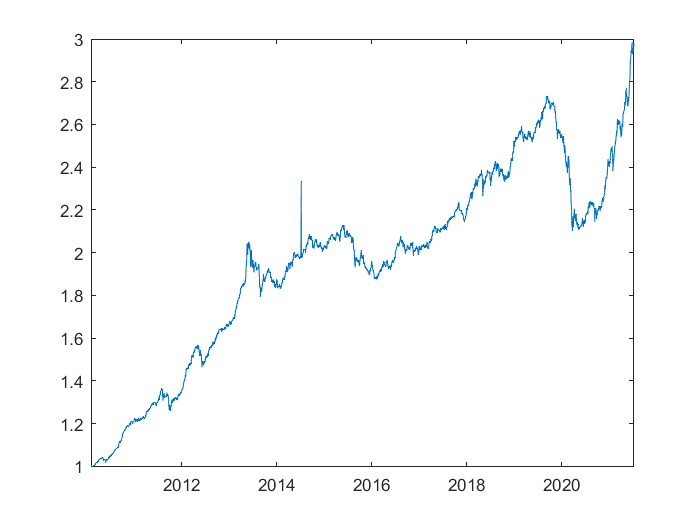

plot (portfolioValue.Time, portfolioValue.Variables)


%Asset area plot
time = bt.Positions.SMAStrategyBacktest.Time ;
positions = bt.Positions.SMAStrategyBacktest.Variables ;

Period = yearfrac (time(1), time(end))

period = 11.4493

PortValue = portfolioValue.Variables ;
CAGR = (PortValue (end))^(1/Period)-1

CAGR = 0.0999

% h = area (time, positions)

% assetAreaPlot (bt, 'SMAStrategyBacktest')

toc

Elapsed time is 44.627701 seconds.


Local functions

function InitialWeights = ComputeInitialWeights (SignalTT) 
% Compute initial weights based on most recent signal.

Signals = SignalTT.Variables ;
nAssets = size (Signals, 2) ;
FinalSignal = Signals (end, :) ;
buys = FinalSignal == 1 ;
InitialWeights = zeros (1, nAssets) ;
InitialWeights (buys) = 1/nAssets ;

end


function new_weights = CrossoverRebalanceFcn (Current_Weights, SignalTT) 
% Signal crossover rebalance function.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Start with current weights
new_weights = Current_Weights ;

% Sell existing long positions where the signal has turned from 1 to 0
idx = CrossoverSignal(end,:) == 0 ;
new_weights (idx) = 0 ;

% Find new crossover (signal has turned from 0 to 1)
idx = and (CrossoverSignal (end-1,:) == 0, CrossoverSignal (end,:) == 0 ) ;

% Bet sizing
AvailableCapital = 1 - sum (new_weights) ;
UninvestedAssets = 1 - sum (new_weights == 0) ;
new_weights (idx) = AvailableCapital / UninvestedAssets ;

end


function assetAreaPlot(backtester,strategyName)
% Plot the asset allocation as an area plot.

t = backtester.Positions.(strategyName).Time;
positions = backtester.Positions.(strategyName).Variables;
h = area(t,positions);
title(sprintf('%s Positions',strrep(strategyName,'_',' ')));
xlabel('Date');
ylabel('Asset Positions');
datetick('x','mm/dd','keepticks');
xlim([t(1) t(end)])
oldylim = ylim;
ylim([0 oldylim(2)]);
cm = parula(numel(h));
for i = 1:numel(h)
    set(h(i),'FaceColor',cm(i,:));
end
legend(backtester.Positions.(strategyName).Properties.VariableNames)

end